# Ex02. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1.1. Develop 7 charts of LTI system function

This assignment involves generating seven charts that illustrate the fundamental behavior of **LTI systems** as described in the problem set. The discrete signals are defined with a variable τ ranging from -10 to 10 with an increment of 0.01. Assuming the constant a = 0.5, this section analyzes the behaviors of x(τ) and h(t-τ), and visualizes the resulting convolution y(t).

a = 0.5;
tau = -10:0.01:10;
x = @(t) heaviside(t);
h = @(t) exp(-a .* t) .* heaviside(t);

figure('Position', [100, 100, 600, 1000]);


subplot(4,2,1);
    p1 = plot(tau, x(tau));
    title('1. x(\tau) signal');
    xlabel("\tau");
    ylabel("Amplitude");
    set(p1, 'Color', 'r');
    set(p1, 'Marker', '^');
    grid on;

subplot(4,2,2);
    p2 = plot(tau, h(tau));
    title('2. h(\tau) signal');
    xlabel("\tau");
    ylabel("Amplitude");
    set(p2, 'Color', 'r');
    set(p2, 'Marker', '^');
    grid on;

t = -2

t = -2

subplot(4,2,3);
    p3=plot(tau, x(t-tau));
    title(['3. x(', num2str(t), '-\tau)']);
    xlabel("\tau");
    ylabel("Amplitude");
    set(p3, 'Color', 'g');
    set(p3, 'Marker', '+');
    grid on;

subplot(4,2,4);
    p4=plot(tau, h(t-tau));
    title(['4. h(', num2str(t), '-\tau)']);
    xlabel("\tau");
    ylabel("Amplitude");
    set(p4, 'Color', 'g');
    set(p4, 'Marker', '+');
    grid on;
 
t = 3

t = 3

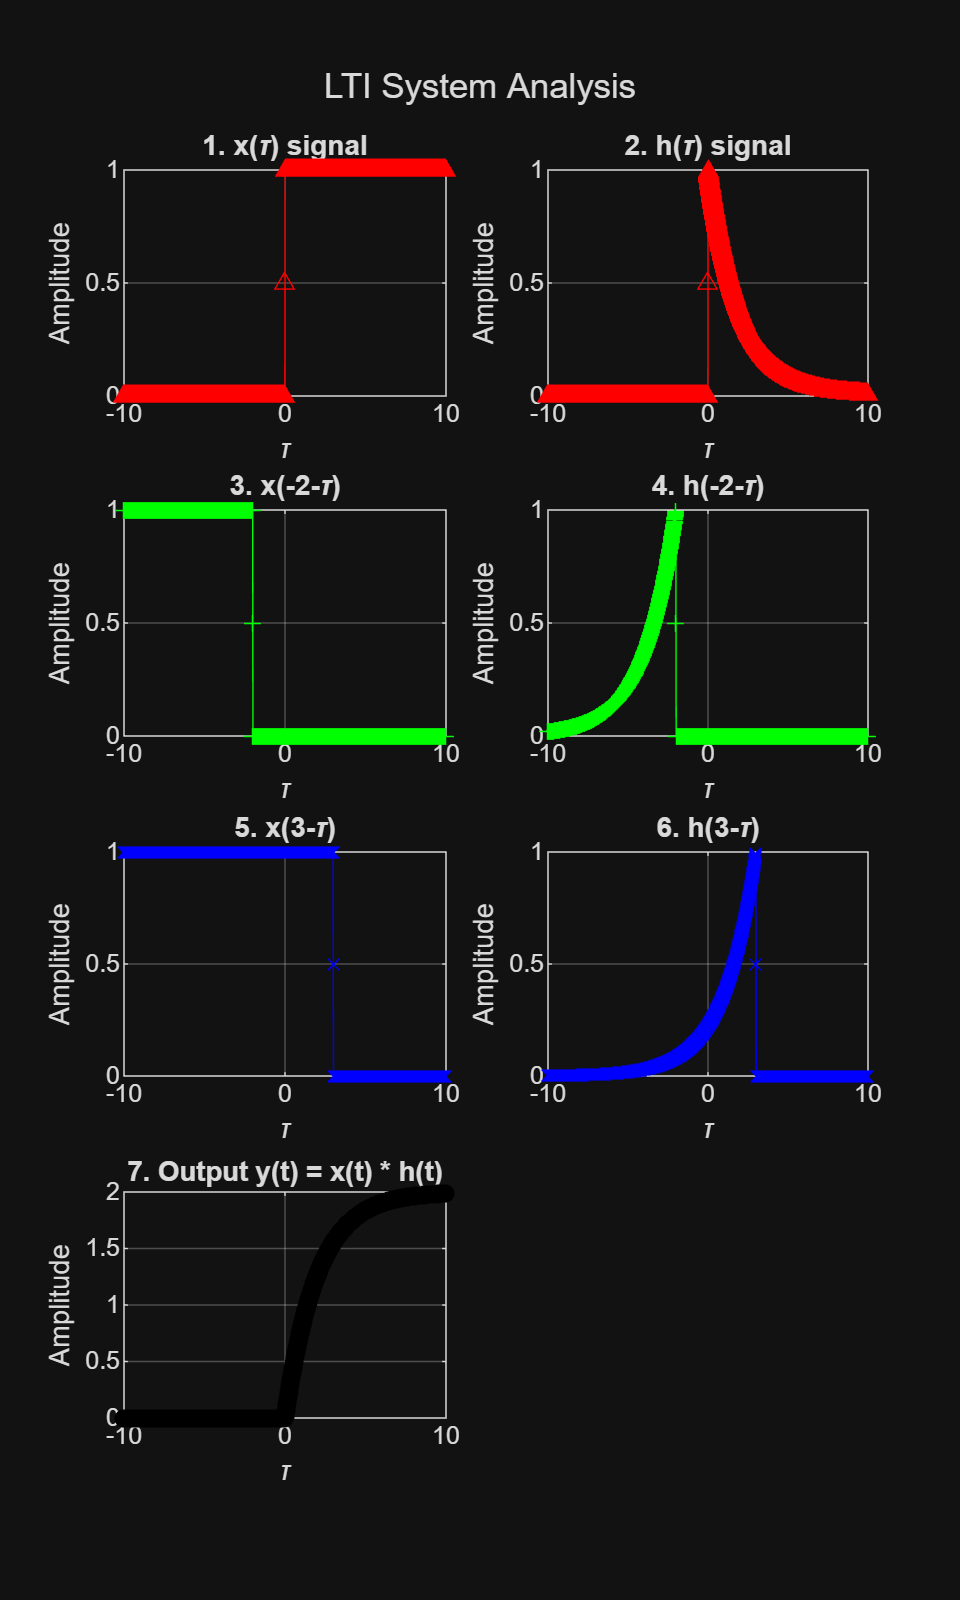

subplot(4,2,5);
    p5=plot(tau, x(t-tau));
    title(['5. x(', num2str(t), '-\tau)']);
    xlabel("\tau");
    ylabel("Amplitude");
    set(p5, 'Color', 'b');
    set(p5, 'Marker', 'x');
    grid on;

subplot(4,2,6);
    p6=plot(tau, h(t-tau));
    title(['6. h(', num2str(t), '-\tau)']);
    xlabel("\tau");
    ylabel("Amplitude");
    set(p6, 'Color', 'b');
    set(p6, 'Marker', 'x');
    grid on;

 subplot(4,2,7);
 y =(1/a) * (1 - exp(-a .* tau)) .* (tau >= 0);
subplot(4,2,7);
    p7 = plot(tau, y);
    title('7. Output y(t) = x(t) * h(t)');
    xlabel("\tau");
    ylabel("Amplitude");
    set(p7, 'Color', 'k');
    set(p7, 'Marker', 'o');
    grid on;

%% Below is the 7 graph required in the assignemnt.
sgtitle('LTI System Analysis'); 

## 1.2. Math Problem 

Below is the snapshot of my answer in fill-blank math problem.